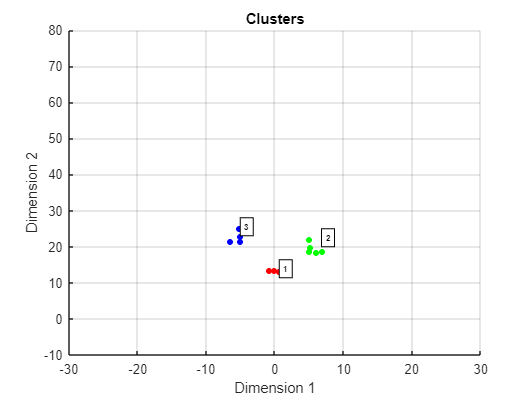

load('testWorkspace.mat');

numObjects = length(simulationData);
allObjectData = cell(numObjects,1);
allClusterData = cell(numObjects,1);

for i = 1:numObjects

    allObjectData{i} = getObjectData(simulationData(i).ObjectDetections);
    allClusterData{i} = [-allObjectData{i}(:,2), allObjectData{i}(:,1)];

end



% Create clusteringDBSCAN object
clusterer = clusterDBSCAN('EpsilonSource','Property','Epsilon',4,'MinNumPoints',3,'EnableDisambiguation',false);
clusterHandle = clusterer(allClusterData{1});
x = plot(clusterer,allClusterData{1},clusterHandle);
axis([-30 30 -10 80]);
hold on;

i = 0;
for i = 1:numObjects
    clusterHandle = clusterer(allClusterData{i});
    plot(clusterer,allClusterData{i},clusterHandle);
    axis([-30 30 -10 80]);
end

function [objectData] = getObjectData(objectDetections)
    % Get number of objects detected for array length
    numDetections = length(objectDetections);

    % Initialize an array of zeros to hold x,y,vx,vy
    objectData = zeros(numDetections,4);

    % Grab values and store in objectData
    % objectData is formated where (i, 1) = x,
    % (i, 2) = y, (i, 3) = vx, and (i, 4) = vy
    for j = 1:numDetections
        objectData(j, :) = [objectDetections{j,1}.Measurement(1);
            objectDetections{j,1}.Measurement(2);
            objectDetections{j,1}.Measurement(4);
            objectDetections{j,1}.Measurement(5)];
    end
end